Basic scenario/map setup

clear all;

sampleRate = 10;
scenario = robotScenario(UpdateRate=sampleRate);

addMesh(scenario, "Plane", Position=[3 2.5 0], Size=[6 5], Color=[0 1 0]);

wallHeight = 1;
wallWidth = 0.05;
wallColor = [1 1 0.8157];

Visualize the map

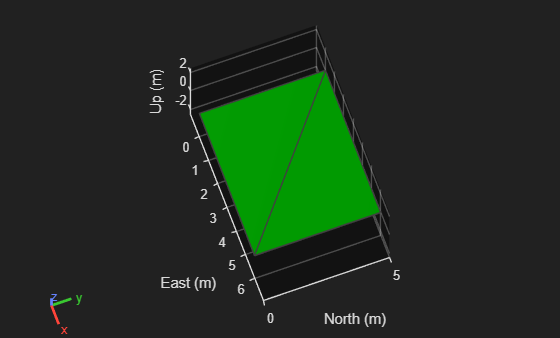

show3D(scenario);
lightangle(-45, 30);
view(70, 70);
grid on;

Setup the basic path

startPosition = [1 1];
chargingPosition = [5 4];

wPts = [[startPosition 0.1]; ...
    1 3 0.1; ...
    2 4 0.1; ...
    4 4 0.1; ...
    5.75 4 0.1];

toa = [0 2 4 7 10];
traj = waypointTrajectory(Waypoints=wPts, ...
    TimeOfArrival=toa, ReferenceFrame="ENU", ...
    SampleRate=sampleRate);

[pos, orient, vel, acc, angvel] = traj.lookupPose(0:1/sampleRate:10);

Setup the robot &  charging station

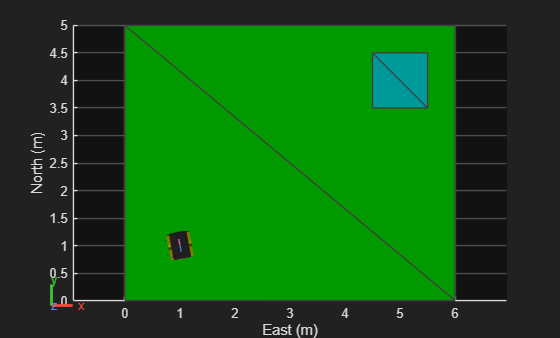

robot = robotPlatform("rst", scenario, RigidBodyTree=loadrobot("clearpathJackal"), ...
                        InitialBasePosition=pos(1,:), InitialBaseOrientation=compact(orient(1)));

addMesh(scenario,"Plane",Position=[5 4 .05],Size=[1 1],Color=[0 1 1]);

chargeStation = robotPlatform("chargeStation", scenario,InitialBasePosition=[5.75 4 0]);
chargeStation.updateMesh("Cuboid", Size=[0.2 1 1], Color=[0 0.8 1]);

show3D(scenario);
lightangle(-45, 30);
view(0, 90);
grid on;

Setup the ultrasonic sensor

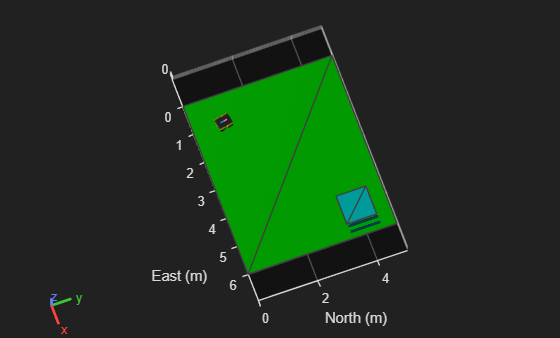

chargingStationProfile = struct("Length", 0.5, "Width", 1, "Height", 1, 'OriginOffset', [0 0 0]);

ultraSonicSensorModel = ultrasonicDetectionGenerator(MountingLocation=[0 0 0], ...
    DetectionRange=[0.03 0.04 5], FieldOfView=[70, 35], Profiles=chargingStationProfile);

ult = robotSensor("UltraSonic", robot, CustomUltrasonicSensor(ultraSonicSensorModel), ...
                    MountingLocation=[0.5 0 0.05]);

figure(1);
ax = show3D(scenario);
lightangle(-45, 30);
view(70, 70);
grid on;

Setup the movement logic

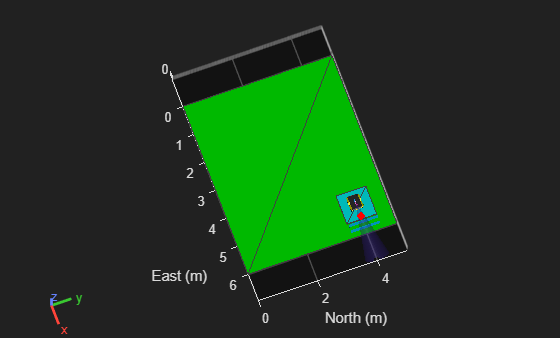

isCharging = false;
i = 1;

setup(scenario);

while ~isCharging
    [isUpdated, t, det, isValid] = read(ult);

    figure(1);
    show3D(scenario);
    view(70, 70);
    light;
    grid on;

    pose = robot.read();
    rotAngle = quat2eul(pose(10:13));
    hold on;

    if ~isempty(det)
        distance = det{1}.Measurement;

        exampleHelperPlotDetectionPoint(scenario, ...
            det{1}.ObjectAttributes{1}.PointOnTarget, ult.Name, pose);

        displayText = ['Distance = ', num2str(distance)];
    else
        distance = inf;
        displayText = 'No object detected!';
    end

    exampleHelperPlotFOVCylinder(pose, ultraSonicSensorModel.DetectionRange(3));
    hold off;

    if distance <= 0.2
        currentMotion = lastMotion;
        currentMotion(1) = currentMotion(1) + 0.01;

        move(robot, "base", currentMotion);
        lastMotion = currentMotion;
        displaytext = ['Detected charger! Distance = ', num2str(distance)];

        if distance <= 0.05
            displaytext = ['Charging! Distance = ', num2str(distance)];
            isCharging = true;
        end
    else
        if i<=length(pos)
            motion = [pos(i,:), vel(i,:), acc(i,:), compact(orient(i)), angvel(i,:)];
            move(robot, "base", motion);
            lastMotion = motion;
            i=i+1;
        end

        pause(1/sampleRate);
    end

    t = text(9, -0.5, displayText, "BackgroundColor", "yellow");
    t(1).Color = "black";
    t(1).FontSize = 10;

    advance(scenario);

    updateSensors(scenario);
end